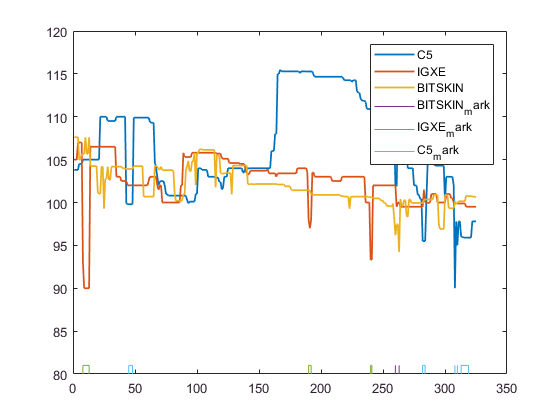

%[cash, investment, noiseMark_C5, noiseMark_IGXE, noiseMark_BITSKIN] = arbitrary_3Market_noiseStrategy(2*ones(44,1), C5, IGXE, BITSKIN, 0.07)
i = 43;
amp = 0.81;
plot(t, C5(i, :), 'LineWidth', 1.3);
hold on
plot(t, IGXE(i, :), 'LineWidth', 1.3);
hold on
plot(t, BITSKIN(i, :), 'LineWidth', 1.3);
hold on
plot(t, amp*noiseMark_BITSKIN(i,:));
hold on
plot(t, amp*noiseMark_IGXE(i,:));
hold on
plot(t, amp*noiseMark_C5(i,:));
legend('C5', 'IGXE', 'BITSKIN', 'BITSKIN_mark', 'IGXE_mark', 'C5_mark');

xlim([0 350])
ylim([80 120])